# Drugi domaci zadatak iz SSE

## Radila: Dragana Ninkovic 2019/0052

# Prvi zadatak

## a) analiticki izrazi

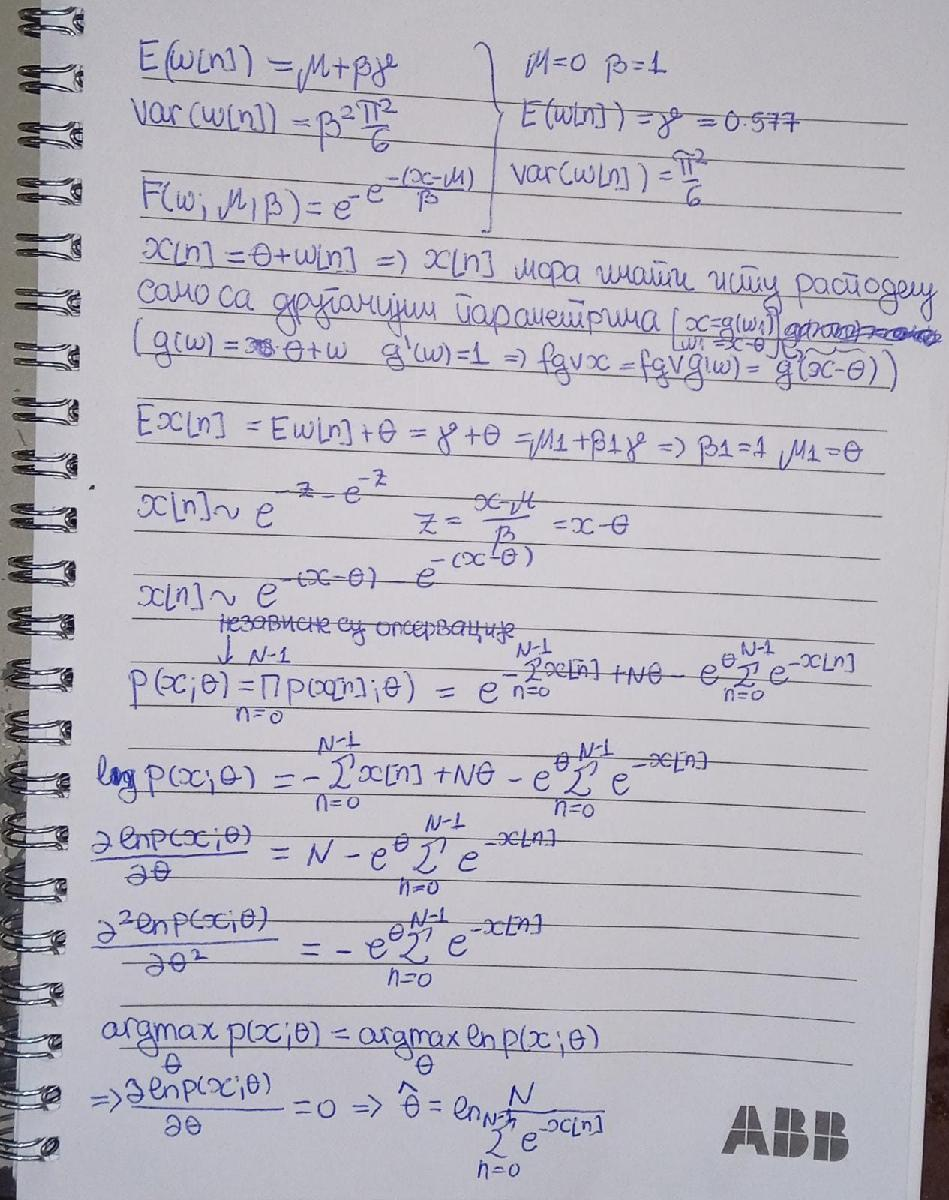

clear; close all; clc;

global x;
global N;

N = 10;
Nr = 100;
syms theta

x = csvread('dom2_zad1.csv');

## optimalni estimator metodom maksimalne verodostojnosti

theta_est_opt = log( N./sum(exp(-x),2) );

## funkcija log verodostojnosti

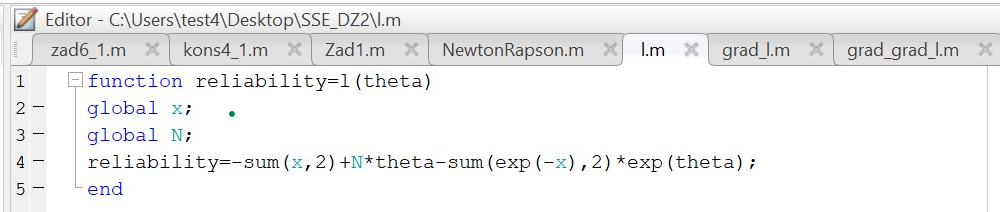

## funkcija prvog izvoda log verodostojnosti

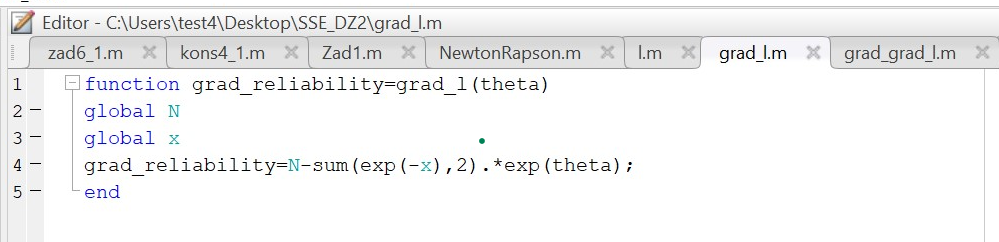

## funkcija drugog izvoda log verodostojnosti

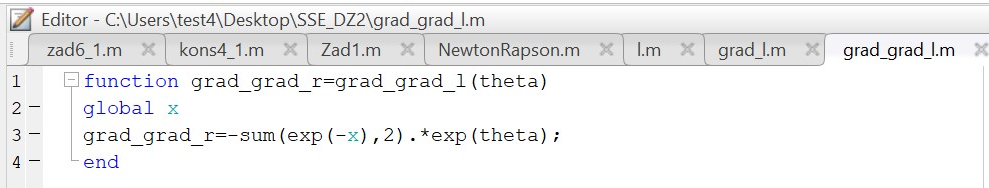

          l_ = l(theta);
     grad_l_ = grad_l(theta);
grad_grad_l_ = grad_grad_l(theta);

## graficki prikaz ovih funkcija

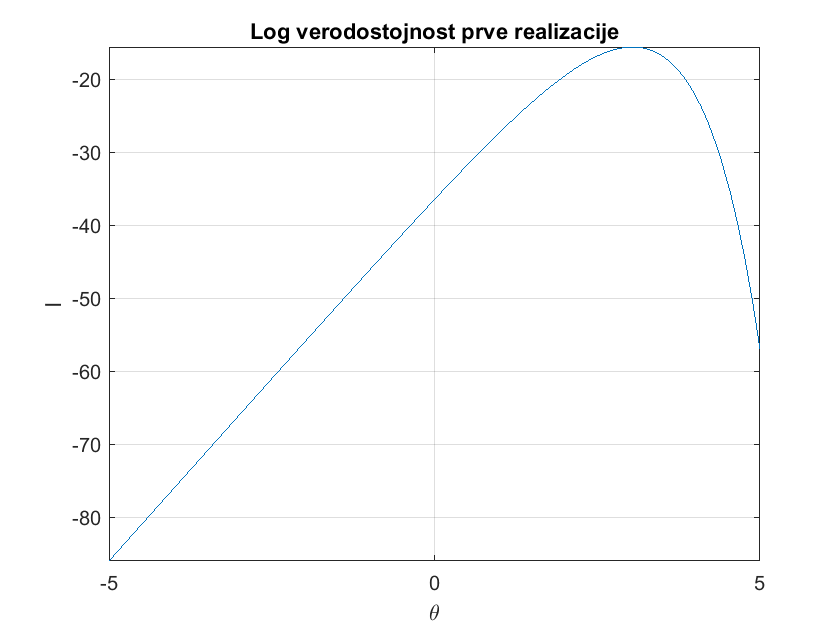

figure(1)
fplot( l_(1,:) )
title('Log verodostojnost prve realizacije'); grid on;
ylabel('l'); xlabel('\theta')

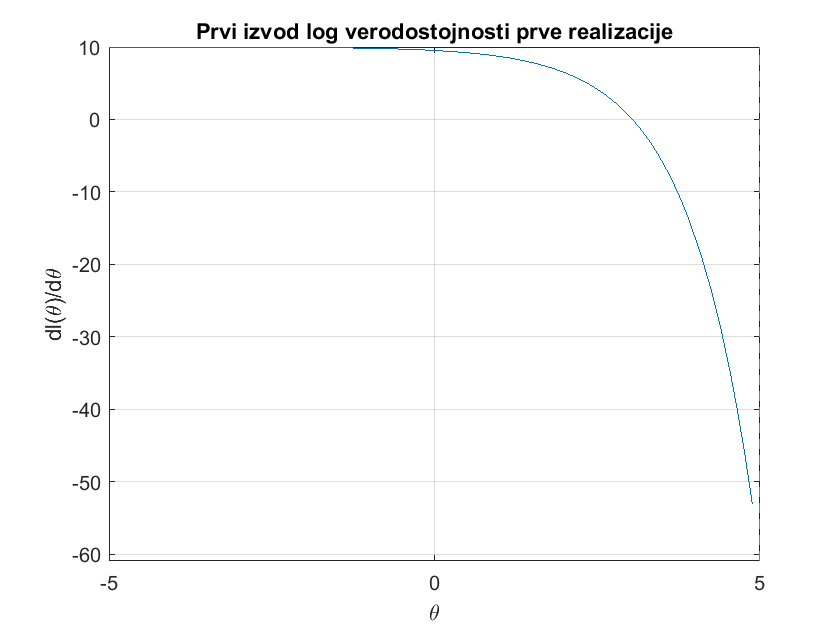

figure(2)
fplot( grad_l_(1,:) );
title("Prvi izvod log verodostojnosti prve realizacije"); grid on;
ylabel('dl(\theta)/d\theta'); xlabel('\theta');

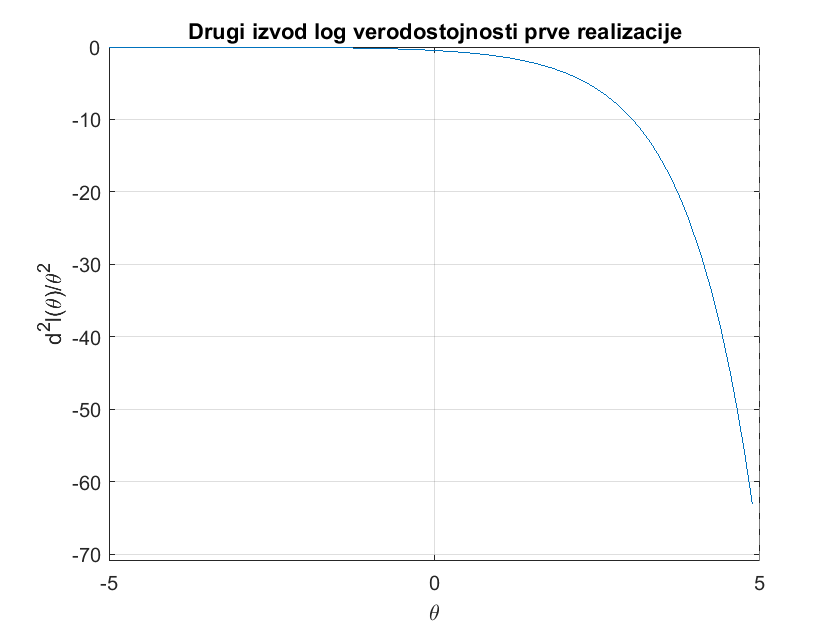

figure(3)
fplot( grad_grad_l_(1,:) );
title('Drugi izvod log verodostojnosti prve realizacije'); grid on;
ylabel('d^2l(\theta)/\theta^2'); xlabel('\theta');

## b) funkcija koja realizuje Newton Rapson-ovu metodu

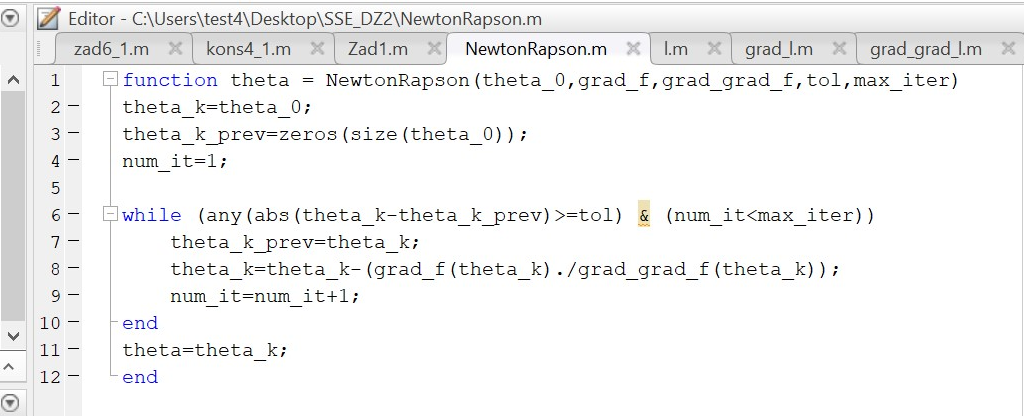

theta = NewtonRapson( 2*ones(Nr,1), @grad_l, @grad_grad_l, 0.00001, 100);

   mu = mean(theta)

mu = 2.3514

sigma = std(theta)

sigma = 0.3154

## provera Newton Rapson-ove metode

all(round(theta, 4) == round(theta_est_opt, 4))

ans = logical
   1


## c) graficki prikaz dobijenih Nr estimacija

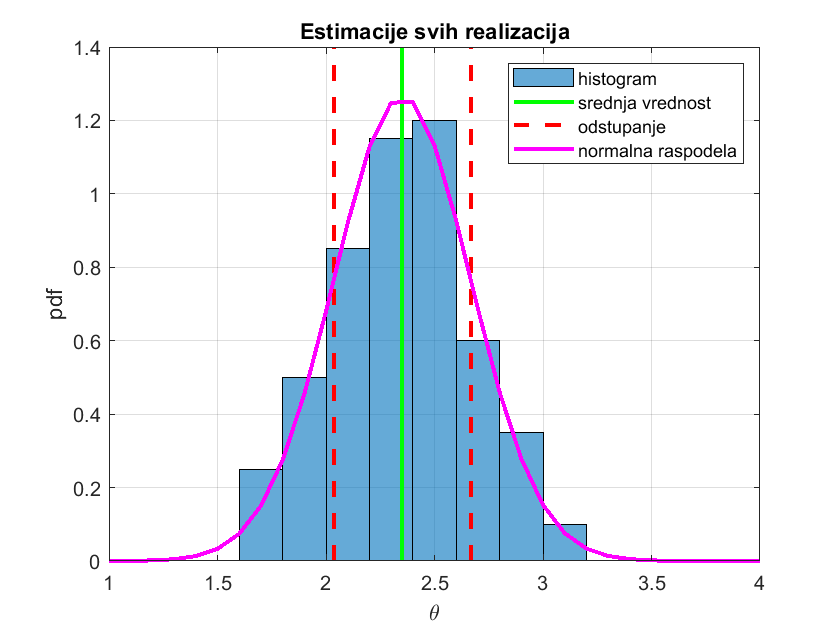

figure(4)
p1 = histogram(theta, 'Normalization', 'pdf');
hold on;
p2 = plot([mu, mu], [0, 1.4], 'Color', 'g', 'LineWidth', 2);
hold on;
p3 = plot([mu - sigma, mu - sigma],[0, 1.4],'Color', 'r', 'LineWidth', 2, 'LineStyle', '--');
hold on;
p4 = plot([mu + sigma, mu + sigma],[0, 1.4], 'Color', 'r', 'LineWidth', 2, 'LineStyle', '--');
hold on;
p5 = plot(1:0.1:4, normpdf(1:0.1:4, mu, sigma), 'Color', 'm', 'LineWidth', 2);
title('Estimacije svih realizacija'); grid on;
ylabel('pdf'); xlabel('\theta');
legend([p1,p2,p3,p5],...
    {'histogram', 'srednja vrednost',...
    'odstupanje', 'normalna raspodela'});
hold off;

# Drugi zadatak

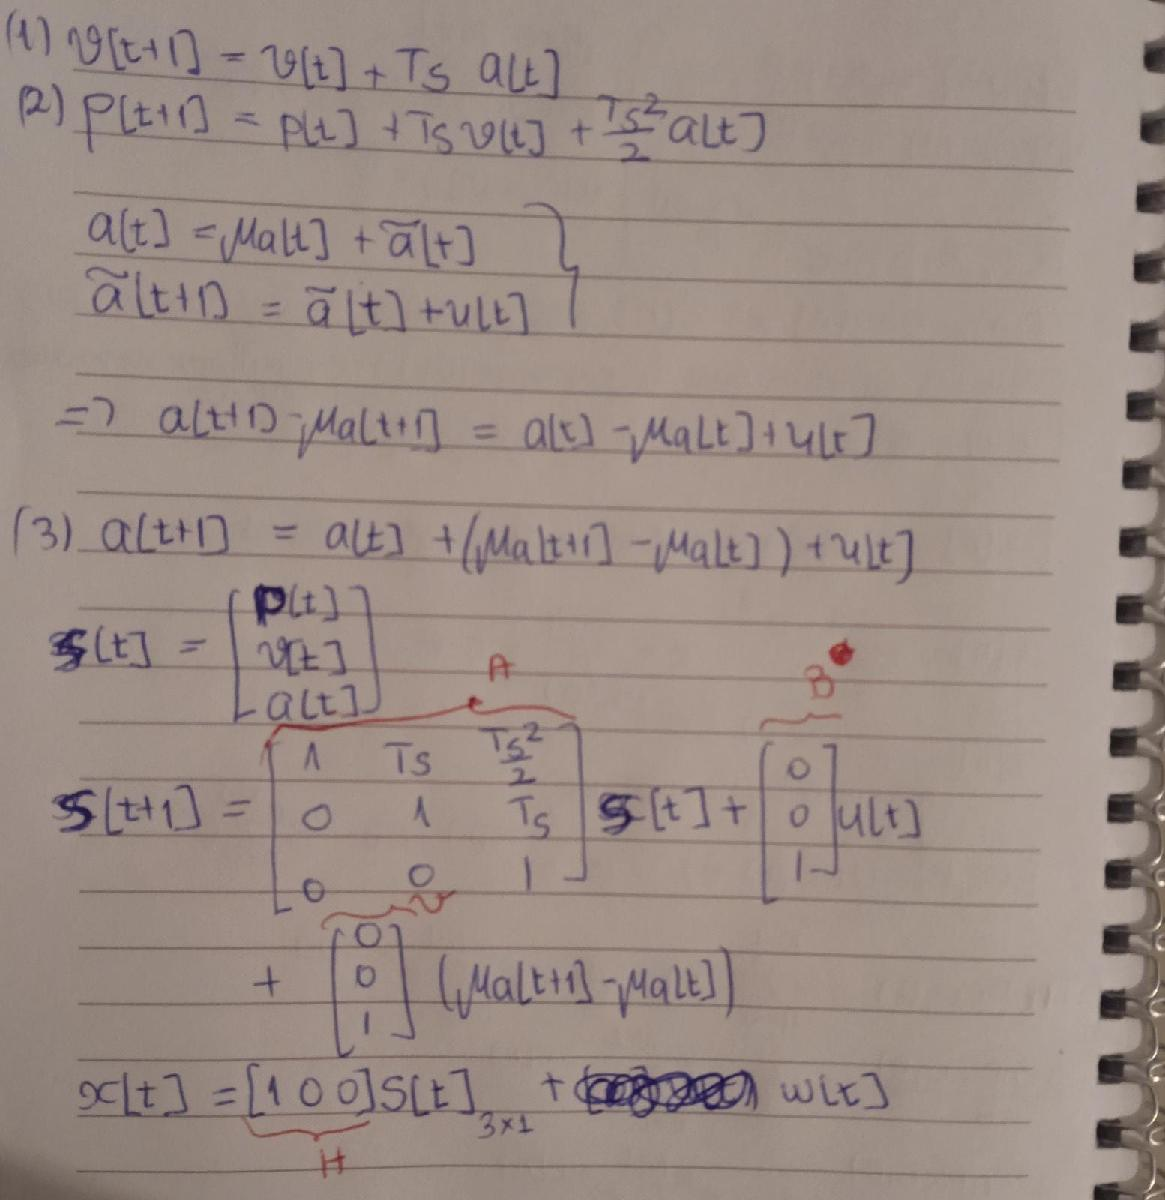

clear; close all; clc;
x = csvread('gnss_data.csv');
n = 0:(length(x) - 1);
Ts = 1;

## sum merenja

% vreme krece od 0 ali indeksiranje ide od 1 zato je npr 44.sekund == 45. odbirak
sigma_w = 10 * ones(size(n));
% raste za 10 od 40. sekunde == 41.odbirak dostize 10+50=60 u 44.skekundi==45.odbirku
sigma_w(41:45) = sigma_w(41:45) + [10, 20, 30, 40, 50];
% od 45.sekunde tj 46.odbirka signal se gubi
sigma_w(46:55) = Inf;
% od 55. sekunde tj 56. odbirka opada od 60 do 10 i on da ostaje const
sigma_w(56:60) = sigma_w(56:60) + [50, 40, 30, 20, 10];

## srednja vrednost a

mu_a = [5 * ones(1, 30), zeros(1, 40), -5 * ones(1, 30)];

## devijacija stohastickog dela ubrzanja koja potice od u

sigma_a = [5 * ones(1, 30), ones(1, 40), 5 * ones(1, 30)];
var_a = (sigma_a./3).^2;% 3 sigma interval jer vrlo retko odstupa

## matrice u modelu stanja

v = [0; 0; 1];% vektor kojim mnozim deterministicki ulaz 
% koji utice samo na ubrsanje
A = [1, Ts, Ts*Ts/2; 0, 1, Ts; 0, 0, 1];
B = [0; 0; 1];
H = [1, 0, 0];
R = (sigma_w).^2;% varijansa suma merenja

## pocetne vrednosti parametara KF

x_est = [0; 0; 5];% pocetne vrednosti vektora koji estimiramo
M_est = [0, 0, 0; 0, 0, 0; 0, 0, 25];% pocetne nesigurnosti
% sigurni smo da u pocetnom trenutku vozilo polazi iz 
% pocetne stanice
% takodje smo sigurni da je onda pocetna brzina 0
% iz navedenih razloga pocetna nesigurnost je nula
% pocetno odstupanje ubrzanja je +/- 5

x_estimirano = zeros(3, length(x) + 1);
M_estimirano = zeros(3, length(x) + 1);
K_ = zeros(3, length(x));

x_estimirano(:,1) = x_est;
M_estimirano(:,1) = [M_est(1,1); M_est(2,2); M_est(3,3)];

## iteracije KF

for i = 1:length(x)
    % Q je promenljiva u vremenu
    Q = var_a(i);
    
    % predikcija
    x_pred = A *  x_est;
     if(i < length(x))
         % dodavanje deterministickog ulaza za sve odbirke 
         % poslednji nije bitan jer je svakako mu_a konstantno na kraju putanje
         x_pred = x_pred + v * (mu_a(i + 1) - mu_a(i));
     end
     
    M_pred = A*M_est*A' + B*Q*B';
    % estimacija
    if i<46 || i>55 
       % kada nije u tunelu
       K = M_pred*H' * (R(i) + H*M_pred*H')^-1;
       x_est = x_pred + K*(x(i) - H*x_pred);
       M_est = (eye(3)- K*H) * M_pred;
       
    else% od 45.sekunde==46.odbirka do 54 sekunde tj 55.odbirka(ukljucujuci njega)
        % signal je izgubljen->stacionarno stanje
       x_est = x_pred;
       M_est = M_pred;
       K = 0;
    end 
    
    x_estimirano(:,i+1) = x_est;
    M_estimirano(:,i+1) = [M_est(1,1); M_est(2,2); M_est(3,3)];
    K_(:,i) = K; 
    
end

## graficki prikaz estimacija dobijenih pomocu KF

## 1) pozicija

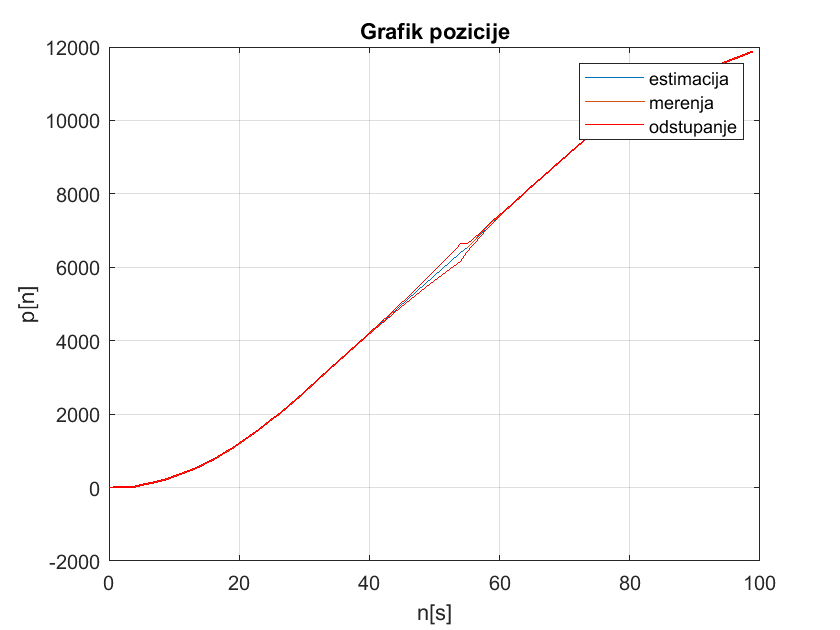

M2sigma = 2 * sqrt(M_estimirano);
% sigma je koren iz varijanse

figure(4)
p1 = plot(n, x_estimirano(1,2:end));
hold on;
p2 = plot (n, x);
hold on
p3 = plot(n, x_estimirano(1,2:end) + M2sigma(1,2:end),'Color','r');
hold on
p4 = plot(n, x_estimirano(1,2:end) - M2sigma(1,2:end),'Color','r');
legend([p1, p2, p3], {'estimacija', 'merenja', 'odstupanje'});
title('Grafik pozicije');grid on;
xlabel('n[s]'); ylabel('p[n]');
xlim([0, 100]); hold off;

## 2) brzina

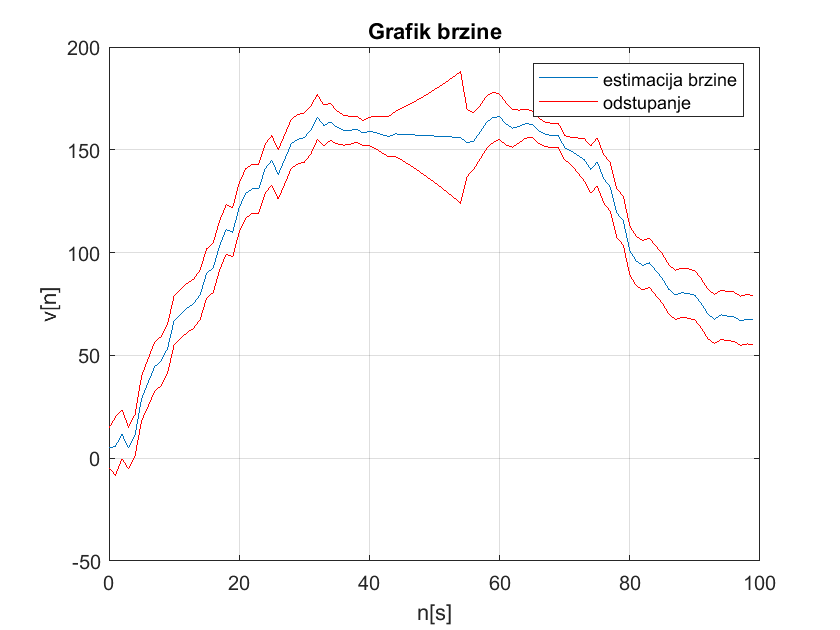

figure(5)
p5 = plot(n, x_estimirano(2, 2:end));
hold on;
p6 = plot(n, x_estimirano(2, 2:end) + M2sigma(2, 2:end),'Color','r');
hold on;
p7 = plot(n, x_estimirano(2, 2:end) - M2sigma(2, 2:end),'Color','r');
title('Grafik brzine'); grid on;
xlabel('n[s]'); ylabel('v[n]');
legend([p5, p6], {'estimacija brzine','odstupanje'});
xlim([0, 100]); hold off;

## 3) ubrzanje

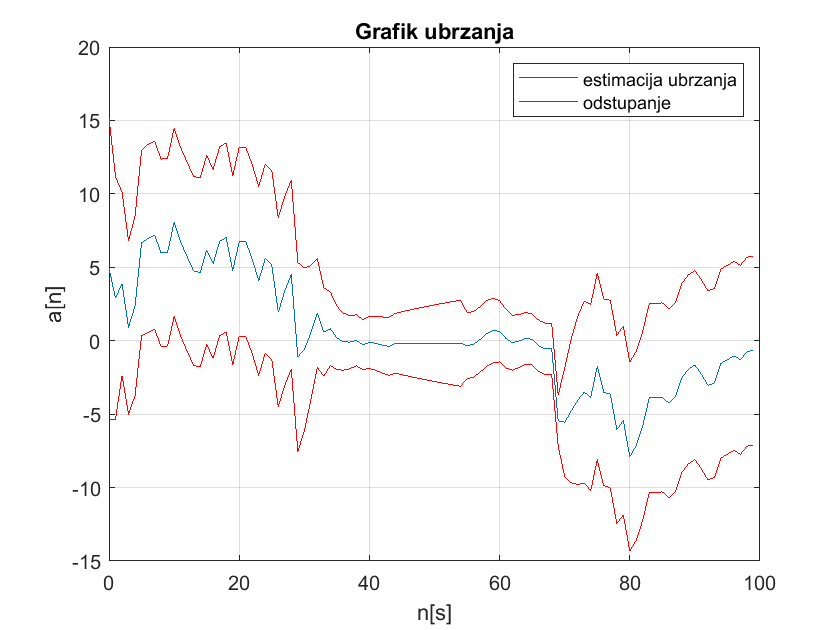

figure(6)
plot(n, x_estimirano(3, 2:end));
hold on;
p8=plot(n, x_estimirano(3, 2:end) + M2sigma(3, 2:end),'Color','r');
hold on;
p9=plot(n, x_estimirano(3,2:end) - M2sigma(3,2:end),'Color','r');
title('Grafik ubrzanja'); grid on;
xlabel('n[s]'); ylabel('a[n]');
legend([p8, p9], {'estimacija ubrzanja', 'odstupanje'});
xlim([0, 100]); hold off;

## 4)Kalmanovo pojacanje

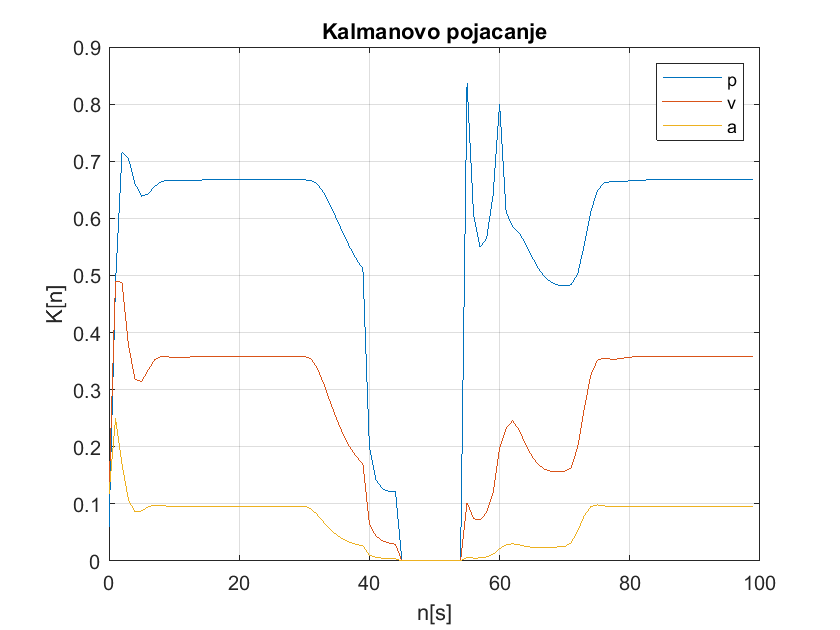

figure(7)
plot(n, K_(1,:))
hold on;
plot(n, K_(2,:))
hold on;
plot(n, K_(3,:));
title("Kalmanovo pojacanje"); grid on;
xlabel('n[s]'); ylabel('K[n]')
legend('p','v','a')
xlim([0, 100]); hold off;